**This file is to explain how to identify the system dynamics of a motor-propeller combination**

First step import the relevant motor-propeller data

clc
close all
clearvars

% Folder in which all test data folders are located
rcbench_folder = 'C:\Users\Tomaso\Desktop\Thesis\main\RC Testbench Data\RC Testbench Data';

% List of folders of the specific tests
test_folder = {...'T-motor F80 Pro 1900 kv - GemFan 6030 4R(green) - 4S'
              ...'T-motor F80 Pro 1900 kv - Qprop 5x4x3 (pink) - 4S'
              ...'T-motor F80 Pro 1900 kv 7x4R (orange) - 4S'
              ...'T-motor MN3515 400 kv - APC 13x10EP - 6S - Pusher'
              ...'T-motor MN3515 400 kv - APC 14x8.5EP - 6S - Pusher'
              ...'T-motor MN3515 400 kv - APC 16x10EP - 6S - Pusher'
              ...'T-motor MN3510 360 kv - APC 11x5.5 EP - 4S'
              ...'T-motor MN3510 360 kv - APC 12x6 EP - 4S'
              ...'T-motor MN3510 360 kv - APC 12x12 EP - 4S'
              ...'T-motor MN3510 360 kv - APC 11x5.5 EP - 6S'
              ...'T-motor MN3510 360 kv - APC 12x6 EP - 6S'
              ...'T-motor MN3510 360 kv - APC 12x12 EP - 6S'
              ...'T-motor MN3510 360 kv - APC 13x10 EP - 6S'
              ...'T-motor MN3510 360 kv - APC 13x10 EP - 6S - Pusher'
              ...'T-motor MN3510 360 kv - APC 14x8.5 EP - 6S'
              ...'T-motor MN3510 360 kv - APC 16x10 EP - 6S'
              ...'T-motor MN3510 360 kv - MF1302R - 4S'
              ...'T-motor MN3510 360 kv - MF1302R - 4S - Pusher'
              'T-motor MN3510 360 kv - MF1302R - 6S'
              ...'T-motor MN3510 360 kv - MF1302R - 6S - Pusher'
              ...'T-motor MN3510 360 kv - MF1302R - 6S - pusher - esc settings'
              ...'T-motor MN3510 360 kv - MF1302R - 6S - Pusher - ESC 48 khz'
              ...'T-motor MN3510 360 kv - MF1302R FW folding hub - 6S - Pusher'
              };

%% Get the data
for n = 1:length(test_folder)
    folder = fullfile(rcbench_folder, test_folder{n});
    data{n} = RCTestbench.getData(folder);
%     data{n} = data{n}.getFOM;
end

Now rename relevant data for ease of use. Only one test data set is used "test1" again for simplicity. 

pwm =[data{1,1}.resp.test1.pwm];
T = [data{1,1}.resp.test1.T]; 
Qm =[data{1,1}.resp.test1.Qm]; 
t = [data{1,1}.resp.test1.t];
rpm = [data{1,1}.resp.test1.RPM];

It is found that the imported data suffers from sensor errors. The thrust data indeed contains Nan at certain indexes. Other variables also contain clearly wrong data points at these same indexes. Let's remove these outliers and substitute them with a guess value using a moving mean method. The datapoints cannot simply be substituted because later steps in the system identification requires for example the time array to be evenly spaced and in ascending order. 

pwm(isnan(T))= nan;
rpm(isnan(T))=nan;
t(isnan(T))=nan;

T =fillmissing(T(2:end),'movmean',10);
pwm = fillmissing(pwm(2:end),'movmean',10);
rpm = fillmissing(rpm(2:end),'movmean',10);
t = fillmissing(t(2:end),'movmean',10);

tnew = linspace(min(t),max(t),size(t,1));
pwm= interp1(t,pwm,tnew);
T= interp1(t,T,tnew);
rpm= interp1(t,rpm,tnew);

Step 2 is to use the user defined polyfitter function to estimate the coefficients of a polynomial function which transforms the pwm signals into T and Qm as registered in the performance tests. Polyfitter returns the coefficients for respectively the T and Qm functions. polyfitter(data,degree_of_poly, debug). By setting debug to 1, it is possible to see how well the polynomial approximation fits the starting data.

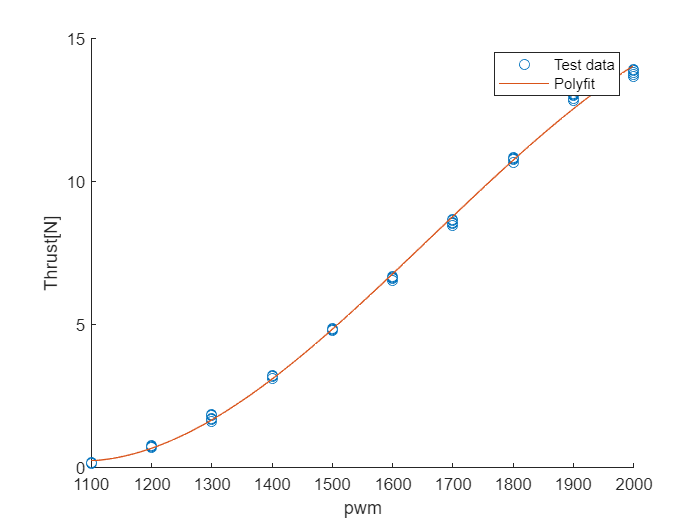

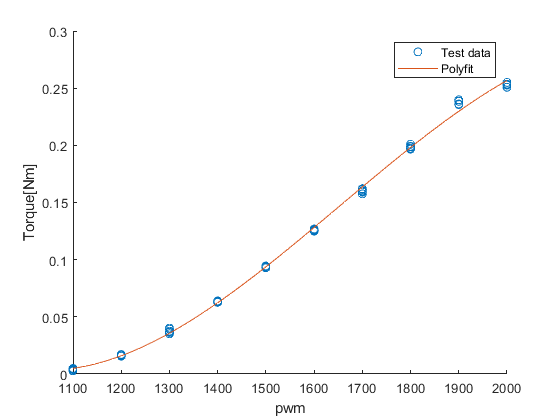

[p_T,p_Qm]= polyfitter(data,3,1);

Now by using the poly coefficients found from the performance test, let's reconstruct what 'performance' thrust would correspond to the pwm signlas registered in the response tests. 

One must realise that by doing so, we are estimating at each pwm data point what would have been the output thrust for a motor with perfect dynamics. This then can serve as a 'target signal' in the system identification of the motor dynamics block.

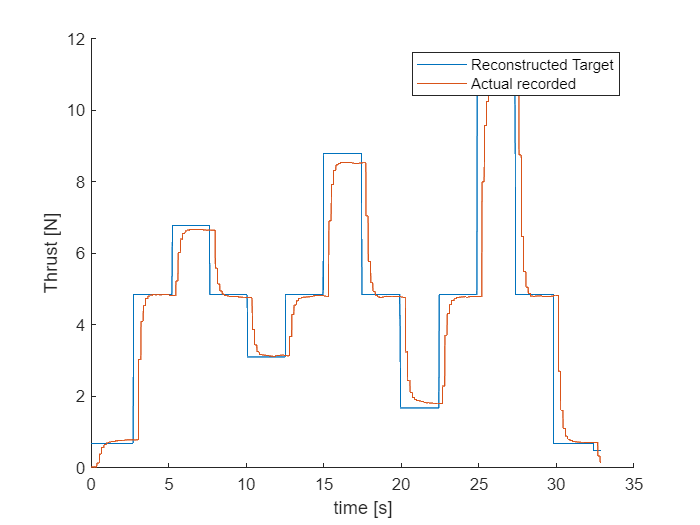

figure(1)
clf
hold on 
plot(tnew, polyval(p_T,pwm))
plot(tnew,T)
xlabel('time [s]')
ylabel('Thrust [N]')
legend('Reconstructed Target','Actual recorded')

Now that we both now the target thrust as well as the actual thrust, we can use the two signals to identify the motor dynamics block. This block will take as input the target thrust, and will output the registered thrust. 

The system identification is done by using matlab's tfest function which takes as input an 'iddata' data set and the number of poles wanted for the transfer function. (e.g. First order dynamics equals 1 pole). 

%test = iddata(T,polyval(p_T,pwm),[],'SamplingInstants',t);
test = iddata(T,polyval(p_T,pwm),t(120)-t(119));
sys = tfest(test,3);

Once the motor dynamics system/block has been identified, we can excite it with the initial target input and check how well the predicted output from the block matches the actual registered output. 

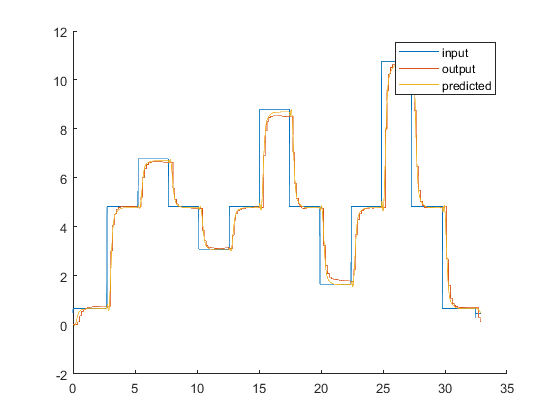

result= lsim(sys,polyval(p_T,pwm),tnew);
figure(2)
clf
hold on 
plot(tnew, polyval(p_T,pwm))
plot(tnew,T)
plot(tnew,result)
legend('input','output','predicted')